# Theoretical Foundations of OFDM Signal Generation with QPSK

Theoretical principles and mathematical formulations behind the OFDM signal generation, modulation, and noise modeling.

## Input parameters: 

ifft_size = 720; % FFT size, or number of subcarriers 
cp_length = 80;
Ld = ifft_size;
Ls = Ld + cp_length;
num_symbols = 20; 
% time domain: each symbol carries 720 subcarriers at time sample i, where i = 1:20
mod_order = 4; % QPSK
dc_index = ifft_size / 2 + 1;

% Number of active subcarriers
num_active = 109; % number of active subcarriers
half = floor(num_active / 2);
active_subcarriers = (dc_index - half):(dc_index + half);  % symmetrical around DC
active_subcarriers(active_subcarriers == dc_index) = [];   % remove DC


`ifft_size = 720`: This determines the **total number of subcarriers** (both active and inactive) in each OFDM symbol. You can think of this as the size of your frequency grid — you have 720 "slots" in the frequency domain.

`cp_length = 80`: Length of the **cyclic prefix** added to each OFDM symbol (used to combat ISI).

`num_symbols = 20`: This refers to the number of **OFDM time-domain symbols** you generate in total — i.e., how many different time samples (each one made from 720 subcarriers) you will create.

**QPSK**: This tells us that each **active subcarrier** carries 2 bits per OFDM symbol (log2(4) = 2)

Think of it like a matrix:

- Each **row** is an OFDM symbol in time (20 total).

- Each **column** is a subcarrier (720 total, but maybe only ~109 are "active").

So you have a **[720 subcarriers × 20 symbols]** structure before applying IFFT + CP.

**Each OFDM symbol uses the full set of subcarriers** (but not all need to be modulated — often you zero-out the edges or DC).

### Why 109 active subcarriers? 

The choice of **109 active subcarriers** is **arbitrary and design-dependent** — it's not fixed by the IFFT size (720).

Even though your **IFFT size is 720**, **not all subcarriers are used for data transmission**.

- DC Subcarrier (Center Frequency): The subcarrier at index 720/2 +1 = 361, corresponds to 0 Hz (DC), it is **not used** because it causes interference and no information is transmitted at 0 Hz.

- Guard Bands: Subcarriers at the edges of the IFFT spectrum are usually **zero-padded** (i.e., set to 0) to prevent **spectral leakage** and simplify filtering. These are called **guard subcarriers**. This is especially important when OFDM signals are adjacent to other channels (e.g., LTE or WiFi).

-  **Pilot Subcarriers (optional): **Some subcarriers are used for **channel estimation** and synchronization — they don't carry data but help the receiver align and equalize.


$$\begin{array}{|l|c|l|}
\hline
\textbf{Region} & \textbf{Subcarrier Indices} & \textbf{Purpose} \\
\hline
\text{1. Guard (left)} & 1\text{ to }306 & \text{Zero-padded (guard)} \\
\text{2. Active (lower)} & 307\text{ to }360 & \text{QPSK data} \\
\text{3. DC} & 361 & \text{Explicitly nulled} \\
\text{4. Active (upper)} & 362\text{ to }415 & \text{QPSK data} \\
\text{5. Guard (right)} & 416\text{ to }720 & \text{Zero-padded (guard)} \\
\hline
\end{array}
$$


## Modulation

 QPSK (Quadrature Phase Shift Keying) is chosen which encodes 2 bits per symbol using orthogonal in-phase (I) and quadrature (Q) components. 

Note that QPSK is equivalent to 4-QAM.


$$s = \frac{1}{\sqrt{2}} \left( \pm1 \pm j \right)
$$



$$\begin{array}{|c|c|}
\hline
\textbf{Bits} & \textbf{Symbol} \\
\hline
00 & \frac{1 + j}{\sqrt{2}} \\
01 & \frac{-1 + j}{\sqrt{2}} \\
10 & \frac{1 - j}{\sqrt{2}} \\
11 & \frac{-1 - j}{\sqrt{2}} \\
\hline
\end{array}
$$


The symbols are normalized to have unit average power:


$$E[|s|^2] = 1$$


%%%%%%%%%%%%% Generate random QPSK data %%%%%%%%%%%%%%
bits_per_symbol = log2(mod_order); % 2 bits per symbol for QPSK 
total_bits = num_active * num_symbols * bits_per_symbol; 

% 109 active subcarriers * 20 time samples * 2 bits per symbol = total bits

bits = randi([0 1], total_bits, 1); % random bits generation [1x4360] bits

symbols = reshape(bits, [], bits_per_symbol); % 2 bits per symbol for QPSK

Reshape the bit stream into a matrix with 2 columns (each row = 1 QPSK symbol)

e.g., bits = [1 0  0 1  1 1  0 0 ...]

symbols = 

   1 0  → Symbol 1  

   0 1  → Symbol 2  

   1 1  → Symbol 3  

   0 0  → Symbol 4

Map bits to QPSK symbols

---------------------------------------

QPSK maps 2 bits to 1 complex symbol:

  - First bit → real part (I)

  - Second bit → imaginary part (Q)

Mapping logic:

  bit 0 → -1, bit 1 → +1

Thus:

  [0 0] → -1 - j

  [0 1] → -1 + j

  [1 0] → +1 - j

  [1 1] → +1 + j

e.g., for [0 1]:

(2 * symbols(:,1) - 1) + 1j * (2 * symbols(:,2) - 1);

(2 * 0 - 1) + 1j*(2 * 1 - 1) = -1 + j 

This mapping is Gray-coded (adjacent symbols differ by one bit),

which reduces bit error rate in noisy channels.

The QPSK symbol is created using:

  I = 2*bit1 - 1

  Q = 2*bit2 - 1

And then combined as: I + j*Q

The optional normalization is:

  qpsk_data = qpsk_data / sqrt(2);

qpsk_data = (2 * symbols(:,1) - 1) + 1j * (2 * symbols(:,2) - 1);
qpsk_data = qpsk_data / sqrt(2);  % Normalized QPSK

## So far we had: 

- Bit Stream Generation

- Modulation (e.g., QPSK) group every **2 bits → 1 complex symbol, **Output: A stream of **complex symbols**.

- Serial to parallel conversion:

Divide the complex symbol stream into blocks of size equal to the **number of active subcarriers** (e.g., 109).

These form **frequency-domain vectors** for each OFDM symbol.

4. Subcarrier mapping: 

Map each block of complex symbols to specific **active subcarriers** in the full IFFT grid (e.g., 720-point vector). Set unused subcarriers and DC to 0.

5. IFFT: Apply **IFFT (e.g., 720-point)** to each frequency-domain OFDM symbol to convert it into a **time-domain signal**.

Output: time-domain complex samples for each OFDM symbol.

6. Cyclic Prefix (CP) Addition: 

- Copy the **last **`cp_length`** samples** of the IFFT output and **prepend** them to the symbol.

- This helps with multipath channel resilience.

7. Parallel-to-Serial Conversion

Convert the CP-added symbols back into a serial stream for DAC transmission.

## OFDM Signal generation

OFDM divides the total channel bandwidth into multiple orthogonal subcarriers. Each subcarrier carries a portion of the data in parallel, making the system resilient to multipath fading and ISI.

Let:

- N: IFFT size (number of subcarriers)

- X[k]: Modulated symbol (e.g., QPSK, M-QAM) on the k-th subcarrier

- x[n]: Time-domain OFDM signal

### 
$$x[n] = \frac{1}{\sqrt{N}} \sum_{k=0}^{N-1} X[k] \cdot e^{j\, \frac{2\,\pi \,k\,n}{N}}, \quad n = 0, 1, \dots, N-1
$$


Subcarrier Allocation and DC Nulling

- Active subcarriers are chosen symmetrically around the center.

- The DC subcarrier (at k = N/2) is set to zero to eliminate carrier leakage.

- Guard bands are left unused to avoid spectral leakage into adjacent channels.

$
$To combat Inter-Symbol Interference (ISI), a Cyclic Prefix of length $L_{\textrm{CP}}$ is added by copying the last $\( L_{\text{CP}} \)
$samples of the time-domain symbol and appending them to the front.

### 
$$$$
x_{\text{cp}}[n] =
\begin{cases}
x[n + N - L_{\text{CP}}], & 0 \leq n < L_{\text{CP}} \\
x[n - L_{\text{CP}}], & L_{\text{CP}} \leq n < N + L_{\text{CP}}
\end{cases}
$$$$


The total OFDM symbol length becomes $L_s = N + L_{\text{CP}}$

The transmit signal is constructed by concatenating multiple CP-extended OFDM symbols:


$$x_{\text{total}}[n] = \left[ \text{CP}_1 + x_1[n],\ \text{CP}_2 + x_2[n],\ \dots \right]
$$


### Why We Use IFFT in OFDM?

OFDM transmits data **in parallel over multiple subcarriers**, each modulated at a different frequency. It uses the **orthogonality of sinusoids** to pack them tightly together without interference.

BUT: generating multiple sinusoids manually would be complex.

Instead of manually modulating 109 carriers with QPSK and summing sinusoids, we use the **Inverse Fast Fourier Transform (IFFT)**.

Each point in the frequency-domain vector you pass to the IFFT acts like the **amplitude/phase of a subcarrier**.

The IFFT outputs a **superposition of all those subcarriers** — a time-domain signal.

Think of OFDM as **encoding frequency data**, and then **IFFT transforms it into the real-world time signal you transmit.**

%%%%%%%%%% OFDM Signal generation %%%%%%%%%%%
ofdm_signal = [];
symbol_matrix = zeros(num_symbols, ifft_size); % 20 x 720 
% Ensuring num_active is consistent with active_subcarriers length (109 -> 108 because of DC null)
num_active = length(active_subcarriers);  

for i = 1:num_symbols
    freq_data = zeros(ifft_size, 1);
    idx_start = (i - 1) * num_active + 1;
    idx_end = i * num_active;
    this_symbol = qpsk_data(idx_start:idx_end);
    freq_data(active_subcarriers) = this_symbol;  % Map to subcarriers
    freq_data(dc_index) = 0;                      % Explicit DC null
    symbol_matrix(i, :) = freq_data;              % For visualization
    time_data = ifft(ifftshift(freq_data)) * sqrt(ifft_size);
    cp = time_data(end - cp_length + 1 : end);
    ofdm_symbol = [cp; time_data];
    ofdm_signal = [ofdm_signal; ofdm_symbol]; % vertical concatenation, for appending this symbol below the existing signal.
end

% Normalize final signal to max amplitude = 3
ofdm_signal = ofdm_signal / sqrt(mean(abs(ofdm_signal).^2));  % Normalize to unit power

### Note: 

 At this point, you have a **baseband complex-valued signal**, which is:

### 
$$s_{\text{baseband}} (t) = I(t) + jQ(t)$$


To transmit it **over a real-valued RF channel**, we need to convert it to a **passband (RF) signal** using **IQ modulation**:

IQ Modulation (Digital-to-Analog + RF Upconversion): 

 generate the **real RF signal** as:

### 
$$s(t) = I(t) . cos(2\pi\, f_c t) - Q(t) . sin(2\pi f_ct)
$$


This maps the complex baseband signal to a **real-valued RF signal** centered at carrier frequency 

## Noise Modeling: Additive White Gaussian Noise (AWGN)

AWGN simulates channel impairments. It is added with a controlled Signal-to-Noise Ratio (SNR):

Target SNR in dB:

### 
$$SNR_{\text{dB}} = 10 \log_{10} \left( \frac{P_{\text{signal}}}{P_{\text{noise}}}\right)
$$


### Convert to linear scale:

### 
$$SNR_{\text{linear}} = 10^{\text{SNR}_{\text{dB}}/10}
$$


### Noise power:

### 
$$P_{\text{noise}} = \frac{P_{\text{signal}}}{\text{SNR}_{\text{linear}}}
$$


### AWGN samples:

### 
$$w[n] = \sqrt{\frac{P_{\text{noise}}}{2}} \cdot \left( \mathcal{N}(0,1) + j \mathcal{N}(0,1) \right)
$$


### Final noisy signal:

### 
$$x_{\text{noisy}}[n] = x_{\text{total}}[n] + w[n]
$$


### Noise Padding

To emulate practical signal capture scenarios (e.g., over-the-air or burst transmissions), noise-only regions are added before and after the useful signal.

### 
$$x_{\text{final}}[n] = \left[ w_{\text{before}},\ x_{\text{noisy}}[n],\ w_{\text{after}} \right]
$$


This helps in testing synchronization, thresholding, and signal detection techniques.

% Add in-band noise
% Set stronger noise level
noise_snr_db = 30;  % Try 5 or 10 dB SNR for visible noise floor
signal_power = mean(abs(ofdm_signal).^2);
noise_power = signal_power / (10^(noise_snr_db/10));

% Add broadband complex Gaussian noise
inband_noise = sqrt(noise_power/2) * (randn(length(ofdm_signal),1) + 1j*randn(length(ofdm_signal),1));
ofdm_signal_noisy = ofdm_signal + inband_noise;

% Add noise padding before and after
left_pad = 600;
right_pad = 1000;
noise_std = sqrt(noise_power);
noise_before = noise_std * (randn(left_pad,1) + 1j*randn(left_pad,1));
noise_after  = noise_std * (randn(right_pad,1) + 1j*randn(right_pad,1));

% Final signal
final_signal = [noise_before; ofdm_signal_noisy; noise_after];

% Save
save('OFDM_Rx_Signal.mat', 'final_signal');

## Visualization: Subcarrier Power

% Remove CP and reshape
X_matrix = reshape(ofdm_signal_noisy, Ls, []).';
X_no_cp = X_matrix(:, cp_length+1:end);
X_fft = fft(X_no_cp, [], 2);
X_fft_shifted = fftshift(X_fft, 2);

% Reshape OFDM symbols
num_symbols_actual = length(ofdm_signal) / Ls;
X_matrix = reshape(ofdm_signal_noisy, Ls, num_symbols_actual).';
% Remove CP
X_no_cp = X_matrix(:, cp_length+1:end);  % shape: [num_symbols, Ld]
% FFT of each symbol
X_fft = fftshift(fft(X_no_cp, [], 2), 2);  % shape: [num_symbols, Ld]
power_matrix = abs(X_fft).^2;             % shape: [num_symbols, Ld]
% Pad to full subcarrier length (optional)
full_power = zeros(num_symbols_actual, ifft_size);
full_power(:, :) = power_matrix;  % Since Ld = ifft_size


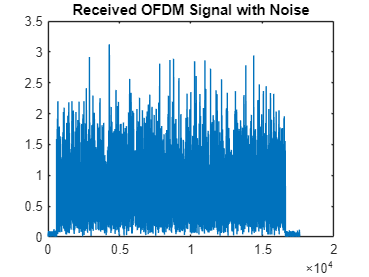

figure(1) 
plot(abs(final_signal));
title('Received OFDM Signal with Noise');

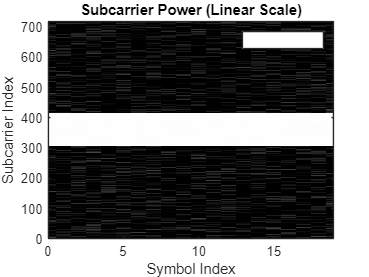

figure(2);
power_db = 10*log10(power_matrix + 1e-12);  % avoid log(0)
imagesc(0:num_symbols-1, 1:ifft_size, power_db.');
colormap(jet);  % better dynamic color range
caxis([max(power_db(:)) - 40, max(power_db(:))]);  % show 40 dB range
axis xy;
colormap(gray);
title('Subcarrier Power (Linear Scale)');
xlabel('Symbol Index');
ylabel('Subcarrier Index');
hold on;
xlim([0 num_symbols_actual - 1]);
ylim([0 ifft_size]);
legend('Guard Band Limits');

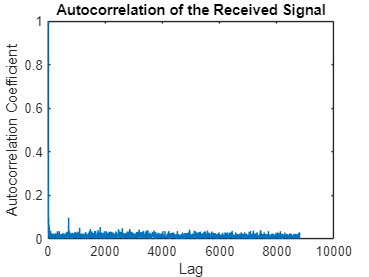

N = length(final_signal);
% Define maximum lag to compute autocorrelation
max_lag = floor(N/2);
% Compute autocorrelation at different lags (shifts)
[Rxx, lags] = xcorr(final_signal, max_lag, 'coeff');
% Consider only positive lags
Rxx_positive = Rxx(lags >= 0);
lags_positive = lags(lags >= 0);
% Plotting Autocorrelation
figure(3);
plot(lags_positive, abs(Rxx_positive));
title('Autocorrelation of the Received Signal');
xlabel('Lag');
ylabel('Autocorrelation Coefficient');

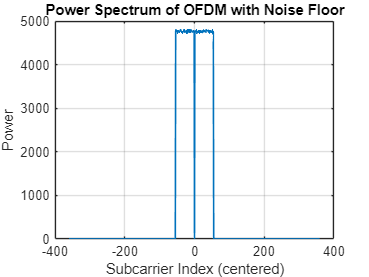

freq_axis = -ifft_size/2 : ifft_size/2 - 1;
avg_power = mean(abs(X_fft_shifted).^2, 1);  % average over symbols
% Plot average PSD
avg_power = mean(power_matrix, 1);
freq_axis = -ifft_size/2 : ifft_size/2 - 1;
figure(4);
plot(freq_axis, avg_power, 'LineWidth', 1.2);
xlabel('Subcarrier Index (centered)');
ylabel('Power');
title('Power Spectrum of OFDM with Noise Floor');
grid on;

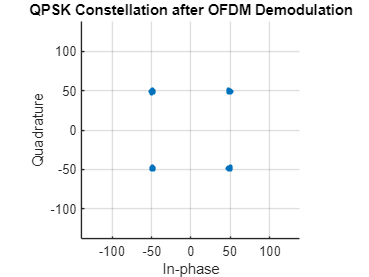

% === Constellation Plot (QPSK Demodulation View) ===
% Extract active subcarriers only (avoid DC and guard bands)
rx_constellation = X_fft(:, active_subcarriers);  % shape: [num_symbols, num_active]

% Flatten all symbols into one long vector (optional)
rx_symbols_flat = reshape(rx_constellation, [], 1);

% Plot constellation for all symbols
figure(5);
scatter(real(rx_symbols_flat), imag(rx_symbols_flat), 10, 'filled');
title('QPSK Constellation after OFDM Demodulation');
xlabel('In-phase');
ylabel('Quadrature');
grid on;
axis equal;
xlim([-2 2] * sqrt(mean(abs(rx_symbols_flat).^2)));  % scale according to average power
ylim([-2 2] * sqrt(mean(abs(rx_symbols_flat).^2)));